## Linear and polynomial fit

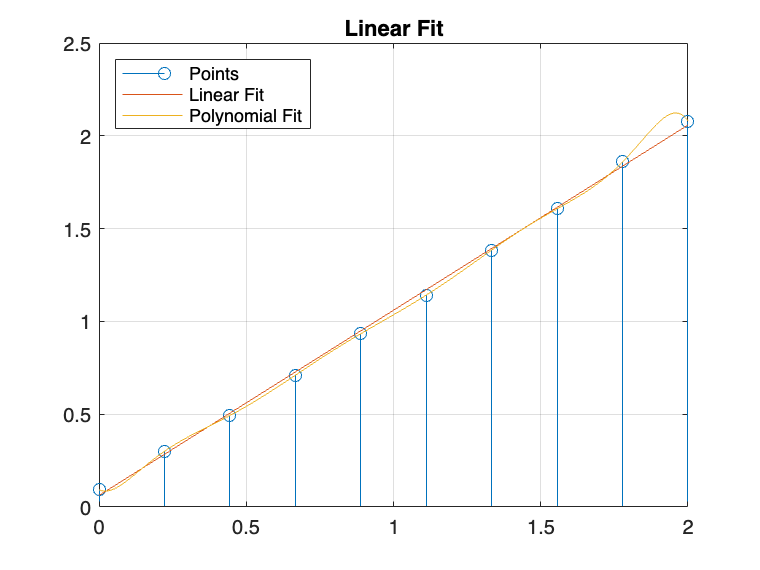

x = linspace(0,2,10);
y = x + 0.1.*rand(1,10);

coeffsLin = LinearFit(x, y);
coeffsPol = PolynomialFit(x, y);
p = linspace(0,2,1000);

Lin = polyval(coeffsLin,p);
Poly = polyval(coeffsPol,p);

stem(x,y)
hold on
plot(p,Lin)
plot(p,Poly)
hold off

grid
xlim([0 2])
title("Linear Fit")
legend("Points","Linear Fit","Polynomial Fit","Location","northwest")

## Splines

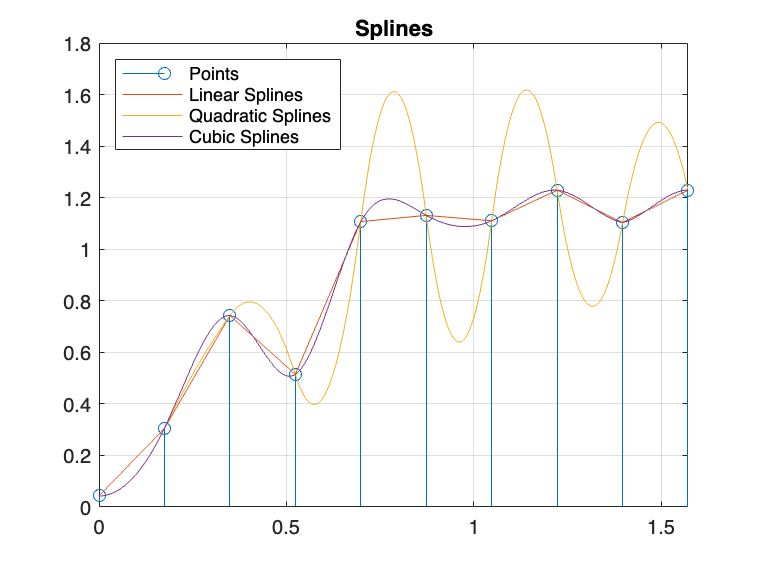

xi = linspace(0,pi/2,10);
fi = sin(xi) + 0.5*rand(1,10);

SL = LinearSpline(xi,fi);
SQ = QuadraticSpline(xi,fi);
SC = CubicSpline(xi,fi);

syms x
stem(xi,fi)
hold on
fplot(SL,[0 pi/2])
fplot(SQ,[0 pi/2])
fplot(SC,[0 pi/2])
hold off

grid
xlim([0 pi/2])
title("Splines")
legend("Points","Linear Splines", "Quadratic Splines","Cubic Splines","Location","northwest")

## Lagrange and Newton interpolation

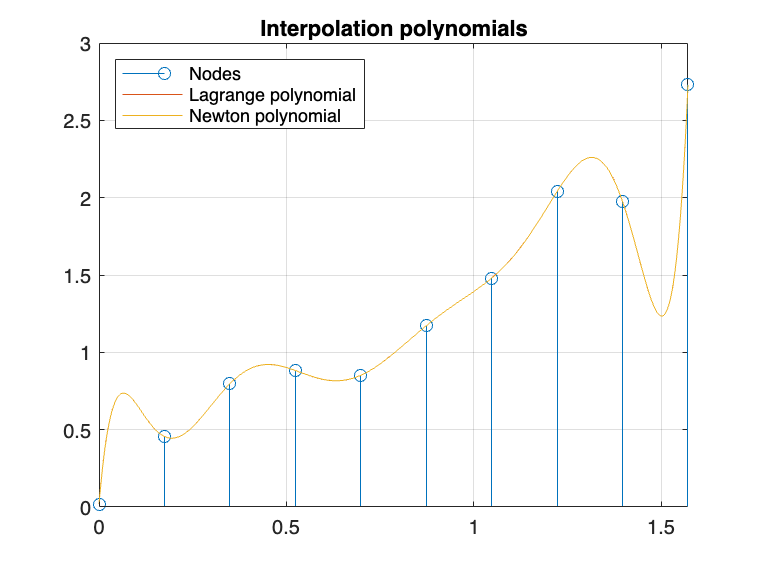

xi = linspace(0,pi/2,10);
fi = sinh(xi) + 0.5*rand(1,10);

pL = LagrangeFit(xi, fi);
pN = NewtonFit(xi,fi);

stem(xi,fi)
hold on
fplot(pL)
fplot(pN)
hold off

grid
xlim([0 pi/2])
title("Interpolation polynomials")
legend("Nodes","Lagrange polynomial","Newton polynomial","Location","northwest")

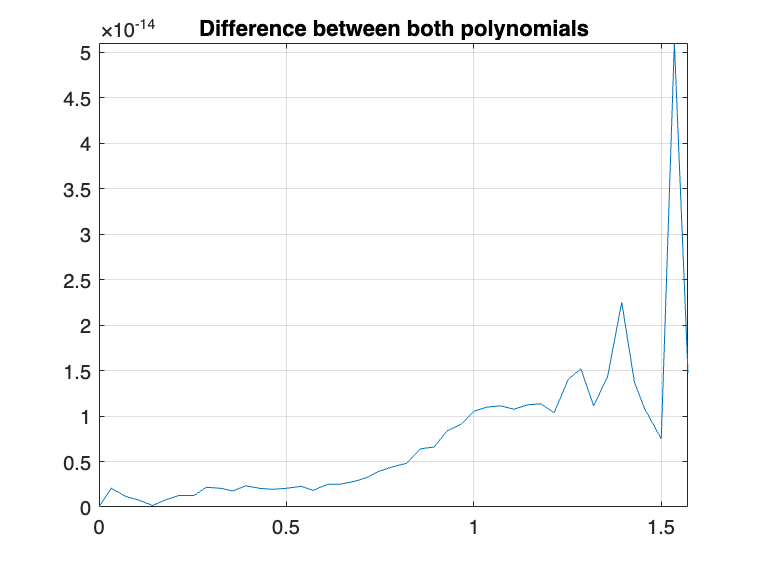


fplot(abs(pN-pL))
grid
xlim([0 pi/2])
title("Difference between both polynomials")

It can be noted that both polynomials are the same, but errors of an order comparable to eps are due to numerical stability.

## Series aproximation

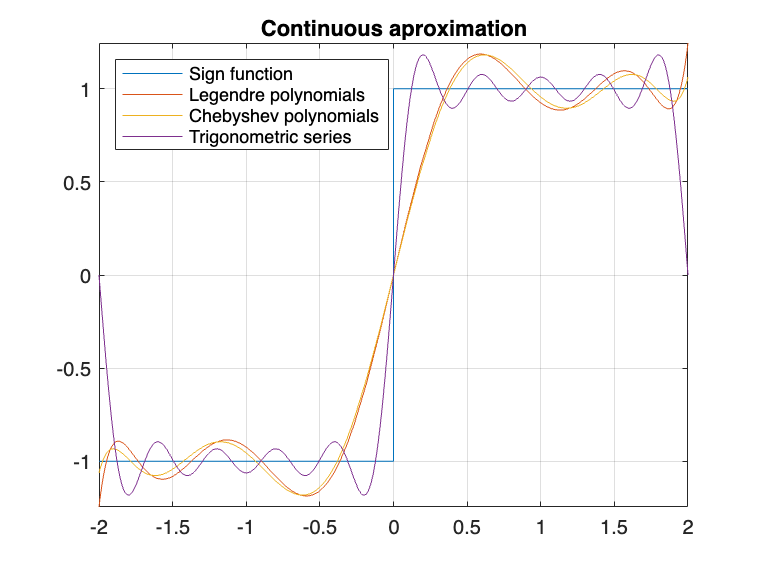

f = @(x) sign(x);

CT = ChebyshevTSeries(f,10,-2,2);
LT = LegendreTSeries(f,10,-2,2);
F = TrigSeries(f,10,-2,2);

fplot(f)
hold on
fplot(LT)
fplot(CT)
fplot(F)
hold off

grid
xlim([-2 2])
title("Continuous aproximation")
legend("Sign function", "Legendre polynomials","Chebyshev polynomials","Trigonometric series","Location","northwest")